# Plotting Electricity Stats by Year and Month

Instructions are in the task pane to the left. Complete and submit each task one at a time.

This code sets up the activity.

com = readmatrix("./data/electricity.xlsx", Sheet='com');
res = readmatrix("./data/electricity.xlsx", Sheet='res');
ind = readmatrix("./data/electricity.xlsx", Sheet='ind');

usage = ind + res + com;
yr = 1990:2019;

## Task 1

When you pass a matrix to the `mean` function, it calculates the average of each column.  Just like with vectors, you can use the `"omitnan"` flag to ignore missing values.

`mean``(``M``,``"omitnan"``)`

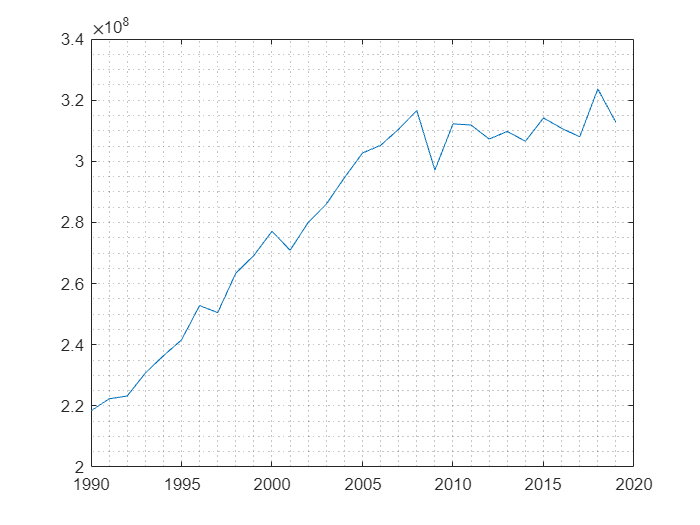

annual = mean(usage, "omitnan");
plot(yr, annual)
grid minor

## Task 2

The `min` and `max` functions also calculate the minimum and maximum of the columns of a matrix.  They omit missing values by default, so you only need to provide the matrix.

`colMins` `=` `min``(``M``)`

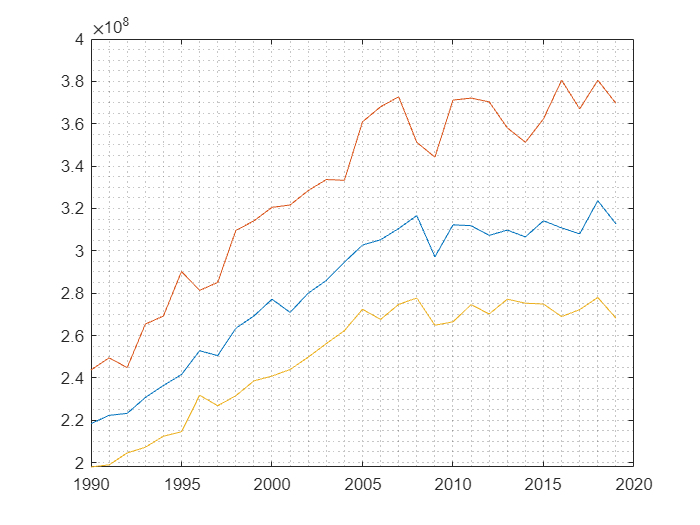

hold on
plot(yr, max(usage))
plot(yr, min(usage))
hold off

## Task 3

To get monthly statistics, you need to calculate the average, minimum, and maximum of the rows.

Many statistical functions accept an optional dimensional argument that specifies whether the operation should be applied to the columns independently (the default) or to the rows.

To get the `mean` of each row, specify `2` as the second input.

`mean``(``M``,``2``)`

`mean``(``M``,``2``,``"omitnan"``)`

You can create a bar plot with the `bar` function.

`bar``(``v``)`

monthly = mean(usage, 2, "omitnan")

monthly = 1.0e+08 *

    2.8995
    2.6879
    2.6660
    2.4895
    2.6276
    2.9078
    3.2339
    3.2775
    3.0143
    2.6748


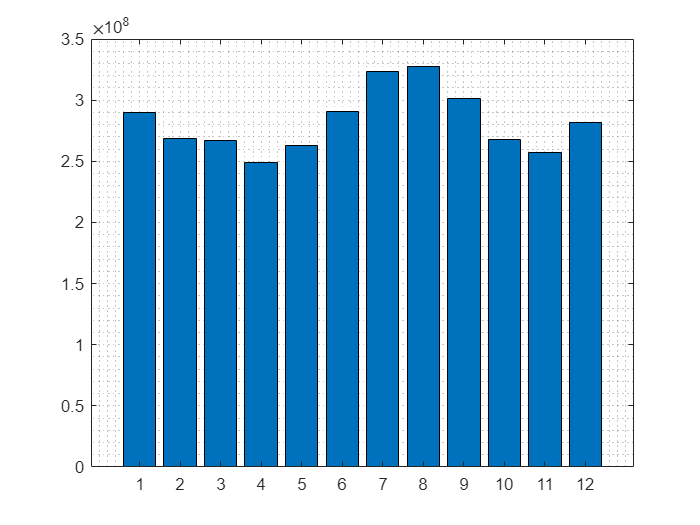

bar(monthly)
grid minor

## Task 4

Some statistical functions are comparison functions, like `min` and `max`.  You can specify the dimension as the third input.  Skip the second input with square brackets, `[]`.

`min``(``A``,``[]``,``dim``)`

To calculate a row statistic, specify the dimension as `2`.  

maxUsage = max(usage, [], 2)

maxUsage =    343814000
   308243000
   304679000
   277941000
   302747000
   337535000
   374474000
   380561000
   336698000
   308560000


minUsage = min(usage, [], 2)

minUsage =    231033219
   206016978
   206723722
   197909489
   200580649
   219185276
   242999824
   243728457
   236200203
   214119000


## Task 5

You can add plots of different types to the same graph.

`bar``(``v1``)`

`hold` `on`

`plot``(``v2``)`

`hold` `off`

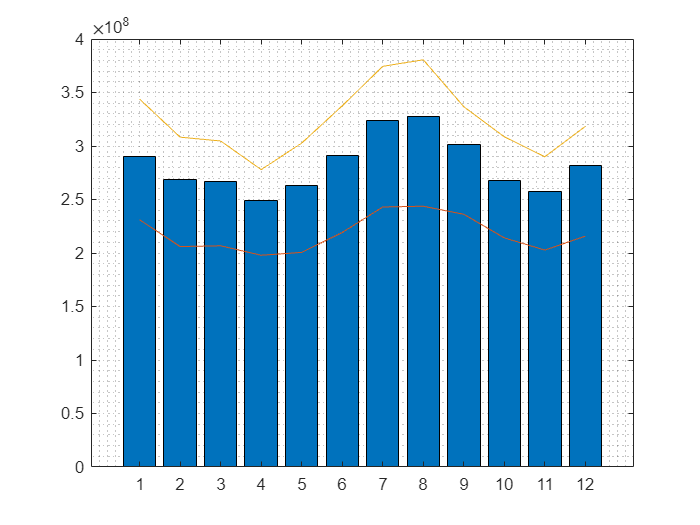

hold on
plot(minUsage)
plot(maxUsage)
hold off

## Task 6

You can also get the mean, minimum, and maximum, of *all of the elements* in array by specifying the dimension as `"all"`.

avgUse = mean(usage, "all", "omitnan")

avgUse = 2.8202e+08

minUse = min(usage, [], "all")

minUse = 197909489

maxUse = max(usage, [], "all")

maxUse = 380561000